## Sun Sync Orbit

J2 = 1e-3;
R_E = 6400; %km
mu = 4e5; %km^3/s^2
n_E = 2*pi/(365*24*3600); %rad/s
a_M = ((3*R_E^2*J2*sqrt(mu))/(2*n_E))^(2/7) %km

a_M = 1.2103e+04

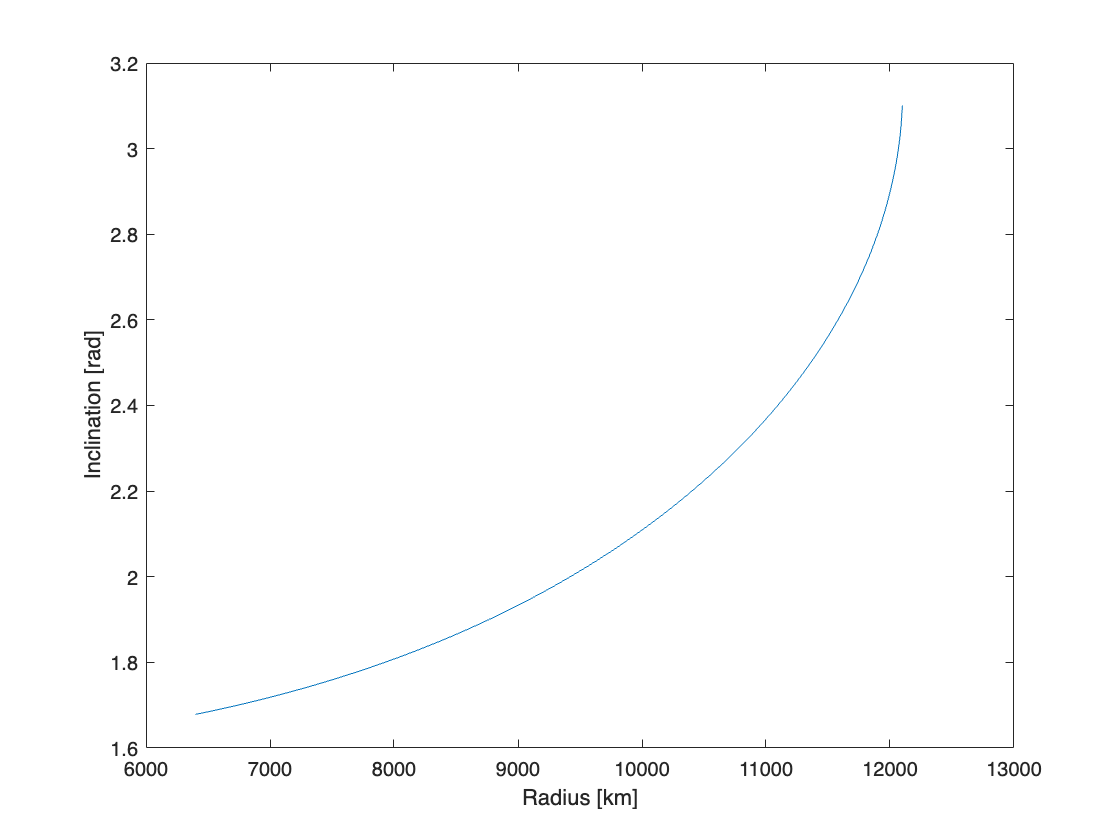

r = R_E:10:a_M; %km
i = acos(-(r/a_M).^(7/2)); %km
plot(r,i);
hold on;
xlabel('Radius [km]');
ylabel('Inclination [rad]');
hold off;

T_max = 2*pi/sqrt(mu)*a_M^(3/2)/3600 %hr

T_max = 3.6743

T_min = 2*pi/sqrt(mu)*R_E^(3/2)/60 %hr

T_min = 84.7752

## Molniya Orbit

T = 12*3600; %s
i = asin(2/sqrt(5)); %rad
omega = deg2rad(-90); %rad
r_p = 7000; %km

a = (T*sqrt(mu)/(2*pi))^(2/3); %km
e = 1-r_p/a; %-
n = sqrt(mu)/a^(3/2); %1/s
omega_dot = 3/2*(n*R_E^2*J2)/(a^2*(1-e^2)^2)*(2-5/2*sin(i)^2) %rad/s

omega_dot = 1.3417e-23

delta_omega = deg2rad(1); %rad
t = delta_omega/omega_dot/3600/24/365 %years

t = 4.1248e+13

f0 = 90; %deg
E0 = acos((e+cosd(f0))/(1+e*cosd(f0))); %rad
t0 = (E0 - e*sin(E0))/n; %s
f1 = 180; %deg
E1 = acos((e+cosd(f1))/(1+e*cosd(f1))); %rad
t1 = (E1 - e*sin(E1))/n; %s
delta_t = 2*(t1 - t0); %s
delta_t/T*100 %percent

ans = 92.2427

i = deg2rad(63.435 - 0.5); %rad
omega_dot = 3/2*(n*R_E^2*J2)/(a^2*(1-e^2)^2)*(2-5/2*sin(i)^2); %rad/s
delta_omega = deg2rad(90); %rad
t = delta_omega/omega_dot/3600/24/365 %years

t = 46.9292

$$F\_r = \begin{array}{l} \frac{m^{2}\,{\sigma_{1}}^{3}\,\left(m\,\left(2\,\beta +2\,\gamma_{g}\right)-\frac{\gamma_{g}\,\mu \,\sigma_{2}}{\sigma_{1}}+\frac{e^{2}\,\mu \,{\sin\left(f\right)}^{2}\,\left(2\,\gamma_{g}+2\right)\,\sigma_{2}}{\sigma_{1}\,\left(e^{2}+2\,\cos\left(f\right)\,e+1\right)}\right)}{a^{3}\,{\left(e^{2}-1\right)}^{3}}\\ \mathrm{where}\\ \sigma_{1}=e\,\cos\left(f\right)+1\\ \sigma_{2}=-e^{2}+2\,\cos\left(f\right)\,e+3 \end{array}$$

$$F\_t = \frac{2\,e\,m^{2}\,\mu \,\sin\left(f\right)\,\left(\gamma_{g}+1\right)\,{\left(e\,\cos\left(f\right)+1\right)}^{3}\,\left(-e^{2}+2\,\cos\left(f\right)\,e+3\right)}{a^{3}\,{\left(e^{2}-1\right)}^{3}\,\left(e^{2}+2\,\cos\left(f\right)\,e+1\right)}$$